## This exercise explores the use of Gaussian filters

`Copyright © 2019 Danica Roth <droth@mines.edu>`

`GNU General Public License`

`Canada Glacier topographic data used in this exercise was downloaded from NCALM and originally published in Telling et al., 2017 (``doi:10.3390/rs9030283).`

Clear working memory and figures (good practice for any Matlab script)

clear
close all
x=-30:0.0001:30;

Set gaussian sigma parameter (standard deviation of the gaussian)

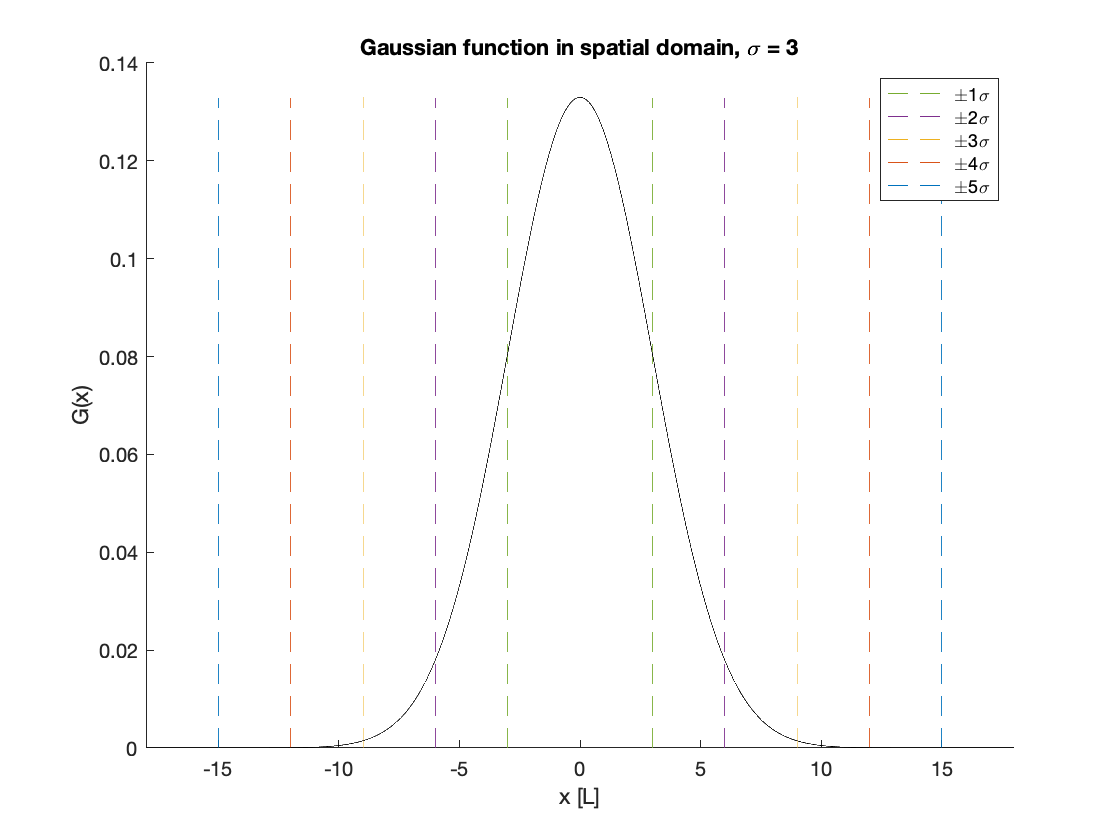

sigma=3;
   
%Define the gaussian function
G=(1./(sqrt(2*pi).*sigma)).*exp(-(x.^2)./(2.*sigma.^2));

%Find sigma intervals
sigmax = sort(sigma.*[-5:-1,1:5]'*[1 1]); % values at +-1sigma, +-2sigma, etc.
sigmay = repmat([0 max(G)],10,1); %yrange to plot lines at sigmax values

%Plot gaussian in spatial domain
figure(1);clf
c=get(gca,'colororder');
cnew=[c(1:5,:);flipud(c(1:5,:))];
set(gca,'ColorOrder',cnew,'NextPlot', 'replacechildren')
px = plot(sigmax',sigmay','--');hold on
plot(x,G,'k');
ylabel('G(x)');xlabel('x [L]')
xlim(6.*sigma.*[-1 1])
title(['Gaussian function in spatial domain, \sigma = ',num2str(sigma)]);
legend(px(6:10),{'\pm1\sigma' '\pm2\sigma' '\pm3\sigma' '\pm4\sigma' '\pm5\sigma' })

Note that $1\sigma =68\ldotp 27%$, $2\sigma =95\ldotp 45%$, $3\sigma =99\ldotp 73%$ of data.

Fourier transformed Gaussian:

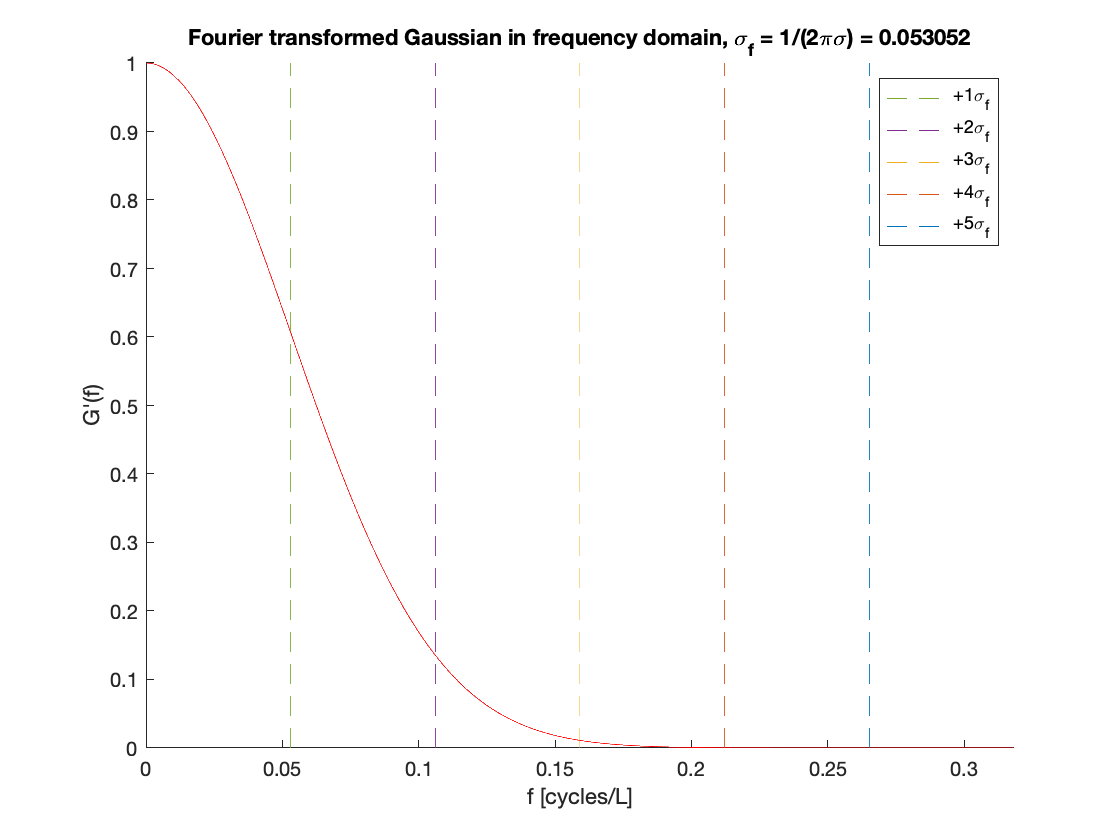

% The standard deviation of the fourier transformed Gaussian is sigma_f,
% which is related to sigma by:
sigma_f=1./(2.*pi.*sigma);

%In wavelengths, this is:
sigma_l=1./sigma_f;

f=x;
lambda=1./f;

% Define the fourier transformed Gaussian function:
G_f=exp(-(f.^2)./(2.*sigma_f.^2));

%Find sigma_f (frequency) and sigma_l (wavelength) intervals
sigma_fx = sigma_f.*[1:5]'*[1 1];
sigma_fy = repmat([0 max(G_f)],5,1);

sigma_lx = 1./sigma_fx;
sigma_ly = sigma_fy;

%Plot fourier transform in frequency space
figure(2);clf
set(gca,'ColorOrder',cnew(6:10,:),'NextPlot', 'replacechildren')
pf = plot(sigma_fx',sigma_fy','--');hold on    
plot(f,G_f,'r');ylabel('G''(f)');xlabel('f [cycles/L]')
xlim([0 6.*sigma_f])
title(['Fourier transformed Gaussian in frequency domain, \sigma_f = 1/(2\pi\sigma) = ',num2str(sigma_f)]);
legend({'+1\sigma_f' '+2\sigma_f' '+3\sigma_f' '+4\sigma_f' '+5\sigma_f' })

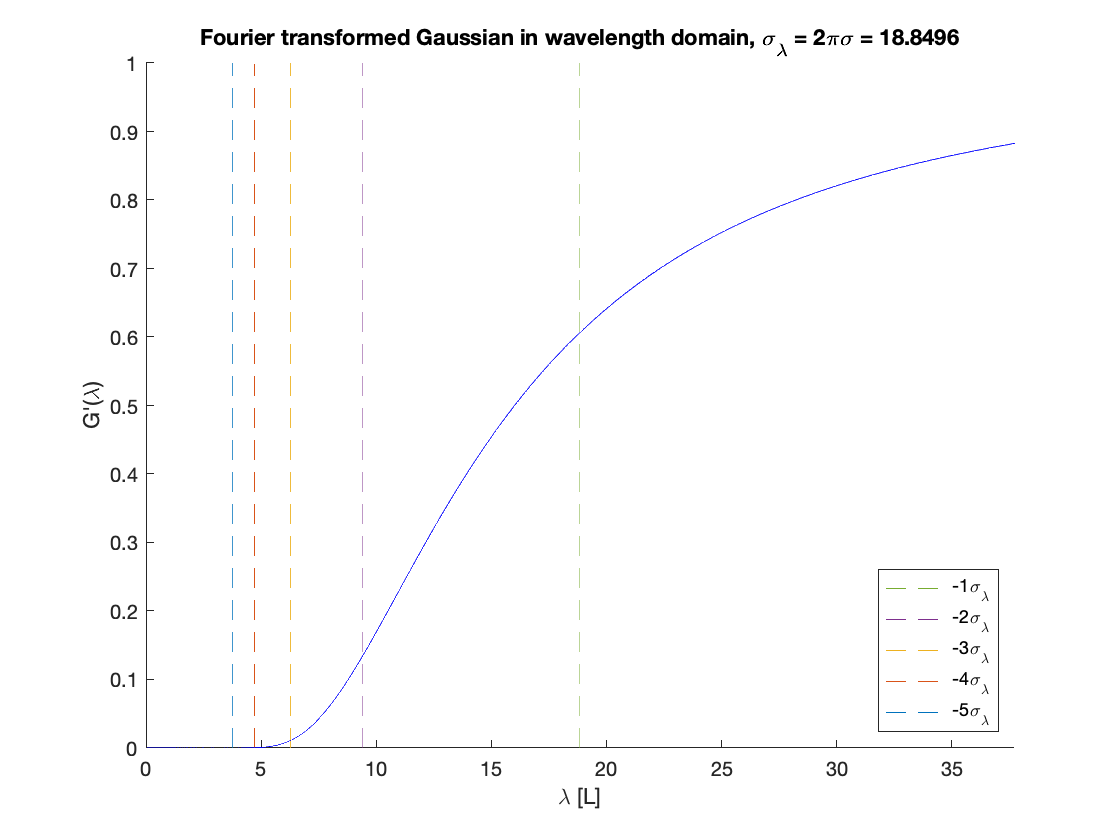


%Plot against wavelength
figure(3);clf
set(gca,'ColorOrder',cnew(6:10,:),'NextPlot', 'replacechildren')
plot(sigma_lx',sigma_ly','--');hold on        
plot(lambda,G_f,'b');ylabel('G''(\lambda)');xlabel('\lambda [L]')
xlim([0 2.*sigma_l])
title(['Fourier transformed Gaussian in wavelength domain, \sigma_\lambda = 2\pi\sigma = ',num2str(sigma_l)]);
legend({'-1\sigma_\lambda' '-2\sigma_\lambda' '-3\sigma_\lambda' '-4\sigma_\lambda' '-5\sigma_\lambda'}, 'location','southeast')

Gaussian frequency response $\hat{G} \left(f\right)$ is essentially zero by $3\sigma_f$.

Gaussian spatial standard deviation $\sigma$ and frequency response standard deviation $\sigma_f$ are related by: $\sigma_f =\frac{1}{2\pi \sigma }$. 

Spatial wavelength $\lambda =\frac{1}{f}$ where $f$ is frequency in $\frac{\textrm{cycles}}{\left\lbrack L\right\rbrack }$. 

Therefore, the $3\sigma_{\lambda \;}$wavelength by which amplitude is nearly fully attenuated is $\lambda_0 =\frac{2\pi \sigma }{3}$.

disp(['sigma = ',num2str(sigma)])

sigma = 3


lambda0 = 2*pi*sigma/3

lambda0 = 6.2832

Gatt=exp(-((1/lambda0).^2)./(2.*sigma_f.^2));
disp(['G(lambda0) = ',num2str(Gatt)]);

G(lambda0) = 0.011109


Inverse: to fully attenuate all wavelengths $<\lambda {\;}_0$, use $\sigma_f ~\frac{f_0 }{3}=\frac{1}{3\lambda_0 }\to \sigma =\frac{3\lambda_0 }{2\pi }$. 

lambda0 = 2.4%Set a minimum wavelength to pass through filter

lambda0 = 2.4000

sigma=3*lambda0/(2*pi)

sigma = 1.1459

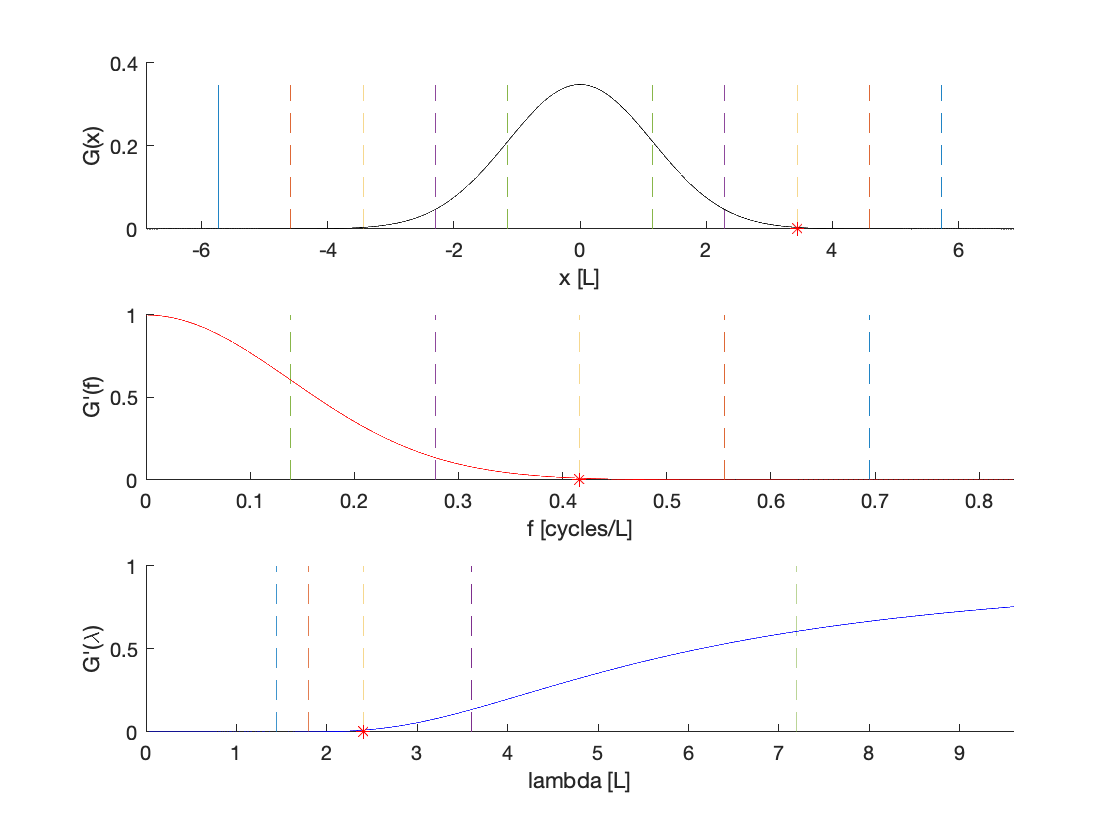


G=(1./(sqrt(2*pi).*sigma)).*exp(-(x.^2)./(2.*sigma.^2));
sigma_f=1./(2.*pi.*sigma);
sigma_l=1./sigma_f;
G_f=exp(-(f.^2)./(2.*sigma_f.^2));

%Find sigma and sigma_f intervals
sigmax = sort(sigma.*[-5:-1,1:5]'*[1 1]);
sigmay = repmat([0 max(G)],10,1);
sigma_fx = sigma_f.*[1:5]'*[1 1];
sigma_fy = repmat([0 max(G_f)],5,1);
sigma_lx = 1./sigma_fx;
sigma_ly = repmat([0 max(G_f)],5,1);


%PLOTS
figure(4);clf
subplot(3,1,1)
c=get(gca,'colororder');
cnew=[c(1:5,:);flipud(c(1:5,:))];
set(gca,'ColorOrder',cnew,'NextPlot', 'replacechildren')
plot(sigmax',sigmay','--');hold on
plot(x,G,'k');
plot(3*sigma,0,'r*')
ylabel('G(x)');xlabel('x [L]')
xlim(6.*sigma.*[-1 1])

subplot(3,1,2)
set(gca,'ColorOrder',cnew(6:10,:),'NextPlot', 'replacechildren')
plot(sigma_fx',sigma_fy','--');hold on    
plot(f,G_f,'r');ylabel('G''(f)');xlabel('f [cycles/L]')
plot(3*sigma_f,0,'r*')
xlim([0 6.*sigma_f])

subplot(3,1,3)
set(gca,'ColorOrder',cnew(6:10,:),'NextPlot', 'replacechildren')
plot(sigma_lx',sigma_ly','--');hold on        
plot(lambda,G_f,'b');ylabel('G''(\lambda)');xlabel('lambda [L]')
plot(lambda0,0,'r*')
xlim([0 4.*lambda0])

## Filter topography

clear
clf

[z, dim] = ReadArcGrid('merced');

% The struct variable dim contains fields describing the coordinates and
% dimensions of Z. These are based on the information extracted from the
% grid file header.
dx = abs(dim.x(2) - dim.x(1)); % grid spacing in the x-direction
dy = abs(dim.y(2) - dim.y(1)); % grid spacing in the y-direction
[Ny Nx] = size(z); % grid dimensions 
x=dim.x-min(dim.x);
y=dim.y-min(dim.y);

% Detrend
Zo = z; % Save the original elevations for later
z = nanDetrend(z);
plane = Zo - z; % Save the least-squares plane for re-trending later


## FILTERING

## Separate rasters into high-pass and low-pass filtered components

$1\sigma =68\ldotp 27%$, $2\sigma =95\ldotp 45%$, $3\sigma =99\ldotp 73%$ of data.

Gaussian frequency response $\hat{G} \left(f\right)$ is essentially zero by $3\sigma_f$.

Gaussian standard deviation $\sigma$ and frequency response standard deviation $\sigma_f$ are related by: $\sigma_f =\frac{1}{2\pi \sigma }$. 

Spatial wavelength $\lambda =\frac{1}{f}$ where $f$ is frequency is $\frac{\textrm{cycles}}{\left\lbrack L\right\rbrack }$. 

Therefore, the wavelength by which amplitude is nearly fully attenuated is $\lambda_0 =\frac{2\pi \sigma }{3}$.

Hence, to fully attenuate all wavelengths $<\lambda {\;}_0$, use $\sigma_f ~\frac{f_0 }{3}=\frac{1}{3\lambda_0 }\to \sigma =\frac{3\lambda_0 }{2\pi }$. 

lambda0=18; %wavelength separating high and low frequencies (in m)
sigma=round(3*lambda0/(2*pi)./dx); %calculate gaussian sigma value
hsize=3.*sigma;
hsize = 2*floor(hsize/2)+1; %make sure hsize is an odd integer

%Filter
[zlp,zhp]=nangaussfilt(z,hsize,sigma);

Unrecognized function or variable 'z'.


% Display shaded relief maps of the low-pass- and high-pass-filtered data

figure(1);clf
ShadePlot(x,y,zlp); title('Low-pass Surface')
figure(2);clf
ShadePlot(x,y,zhp); title('High-pass Surface')

Pull out a random row and column of **z** and treat them as 1D sample vectors to make test periodograms:


%Select a random row (yr) and column (xr) of z
yr = randi(length(y));
xr = randi(length(x));
zx=z(yr,:);
zy=z(:,xr);
zxhp=zhp(yr,:);
zxlp=zlp(yr,:);
zyhp=zhp(:,xr);
zylp=zlp(:,xr);


figure(3)
clf
%Show surface again with lines showing random transect locations + transect topography
subplot(3,5,1:3); shadetransects(x,y,z,xr,yr);
title('original topography')
subplot(3,5,4:5); topotransects(x,y,zx,zy);

subplot(3,5,5+[1:3]); shadetransects(x,y,zlp,xr,yr);
title('low-pass topography')
subplot(3,5,5+[4:5]); topotransects(x,y,zxlp,zylp);

subplot(3,5,10+[1:3])
shadetransects(x,y,zhp,xr,yr);
title('high-pass topography')
subplot(3,5,10+[4:5]); topotransects(x,y,zxhp,zyhp);

## 1D Transect Periodograms

Start with just 1D periodograms of the random row and column of z above.

Calculate the periodogram for each random transect.

% Identify the spatial sampling frequency
fs = 1/dx; %units of samples/meter
fNyquist = fs/2; %Nyquist frequency 
fx = 0:fs/Nx:fNyquist;%frequency vector
fy = 0:fs/Ny:fNyquist;%frequency vector
wx = 1./fx; %wavelengths
wy = 1./fy; %wavelengths
f=fy;
w=wy;

%Calculate 1D, 1-sided power spectra and amplitude spectra using fft
[Afxx,Pfxx] = fft1side(zx);
[Afyy,Pfyy] = fft1side(zy);


%Calculate a 1D periodogram for each of these random samples
% windowx = hamming(length(zx)); %create hamming window to taper signal and avoid edge artifacts
[Pxx,Plxx,Axx,Alxx] = per1s(zx,fx,fs);
[Pyy,Plyy,Ayy,Alyy] = per1s(zy,fy,fs);
[Pxxhp,Plxxhp,Axxhp,Alxxhp] = per1s(zxhp,fx,fs);
[Pyyhp,Plyyhp,Ayyhp,Alyyhp] = per1s(zyhp,fy,fs);
[Pxxlp,Plxxlp,Axxlp,Alxxlp] = per1s(zxlp,fx,fs);
[Pyylp,Plyylp,Ayylp,Alyylp] = per1s(zylp,fy,fs);

*Note that while we selected a random row (y value), this extracts a sample that varies in x (i.e., across multiple columns). Hence Pxx is a periodogram over x, while Pyy is a periodogram over y.*

#### Plot the periodograms:

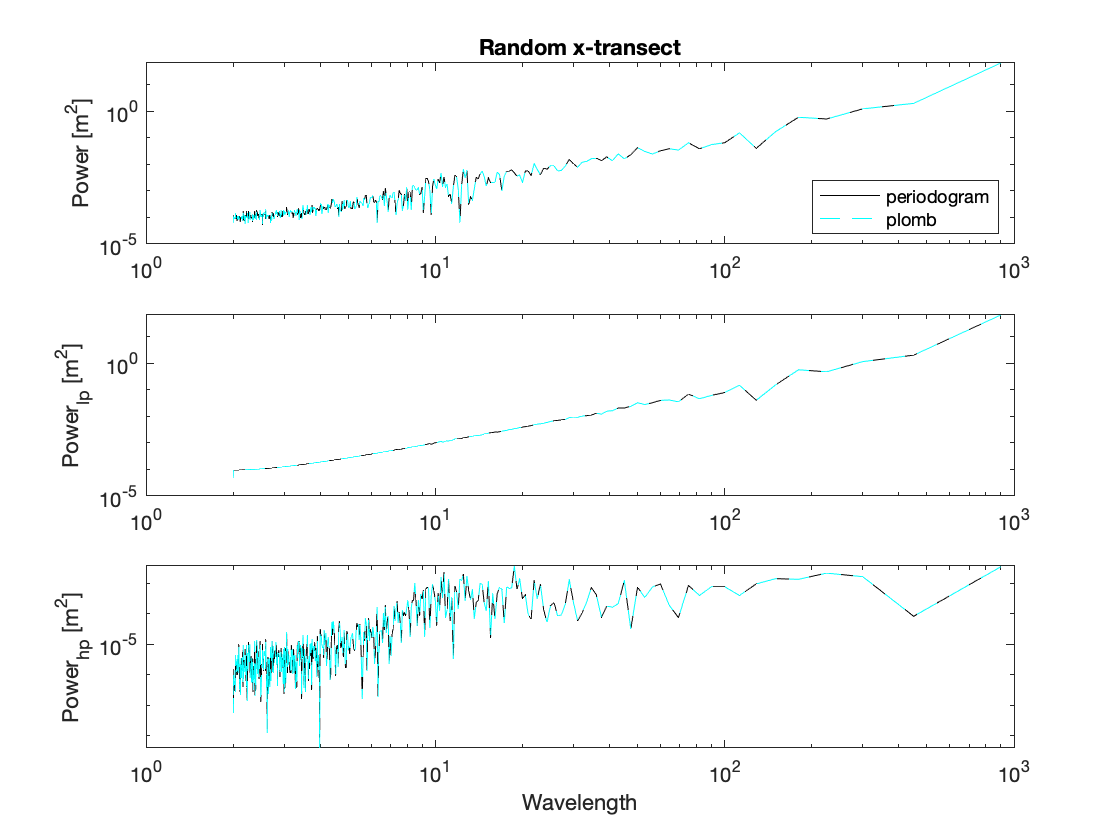

figure(4);clf
plotspectpass(Pxx,Plxx,Pxxlp,Plxxlp,Pxxhp,Plxxhp,wx,'Random x-transect',[]);

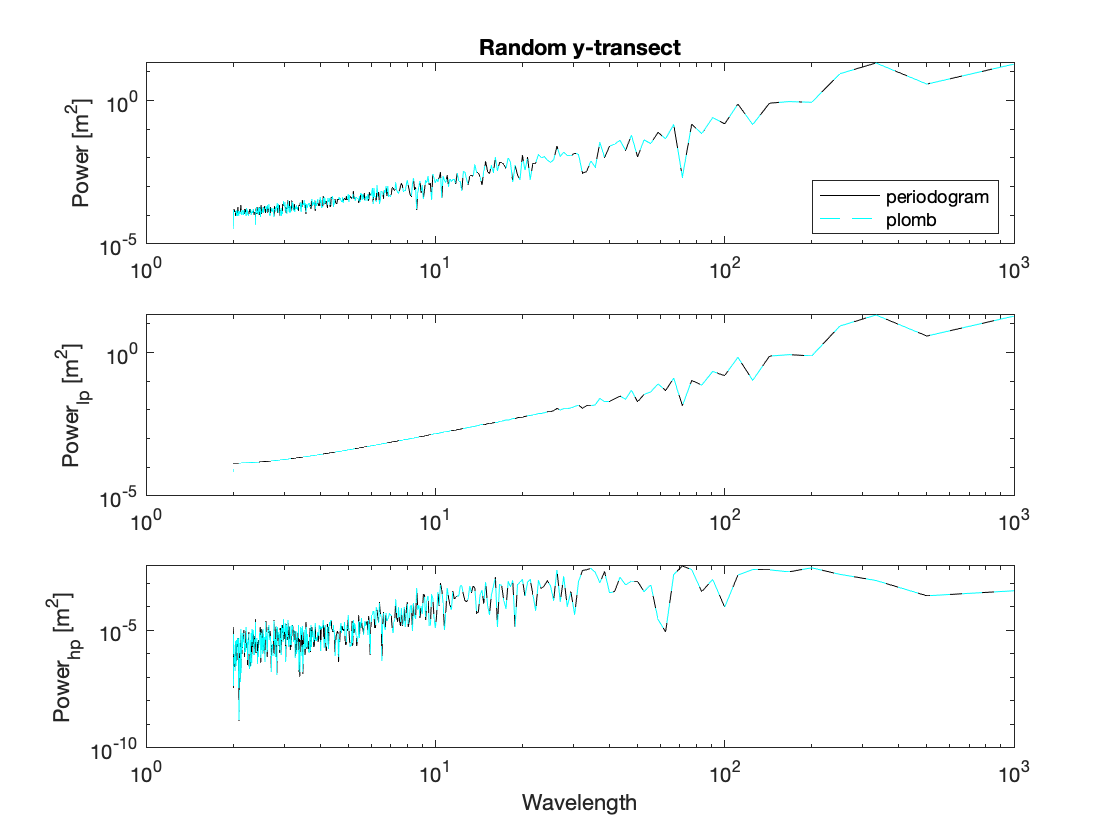


figure(5);clf
plotspectpass(Pyy,Plyy,Pyylp,Plyylp,Pyyhp,Plyyhp,wy,'Random y-transect',[]);

## Functions

#### SPECTRAL CALCULATION FUNCTIONS

function [A,P] = fft1side(z)
    N=numel(z);
    Z = fft(z); %compute fourier transform
    A2 = abs(Z./N); % normalize by number of samples (i.e., multiply by width or sample interval) for 2-sided amplitude spectrum
    A = A2(1:(N-mod(N,2))/2+1); %calculate 1-sided amplitude spectrum (if N=odd, subtract 1 and divide; if even, divide in half; always add 1 for DC component)
    A(2:(end-mod(N-1,2))) = 2.*A(2:(end-mod(N-1,2))); %fold aliased amplitude from duplicate frequencies
    A(1) = 0; %zero out DC component (signal mean)
    P = A.^2; %power spectrum
end

    
function [P,A,f] = periodogram1s(z,f,fs)
    [P,f] = periodogram(z,[],f,fs,'power');
    P = 4.*P; %1-sided power spectra
    A = P.^(1/2); %1-sided amplitude spectra
end

function [Pl,Al,f] = plomb1s(z,f,fs)
    [Pl,f] = plomb(z,fs,f,'power');
    Pl = 2.*Pl;
    Al = Pl.^(1/2);
end

function [P,Pl,A,Al,f,fl] = per1s(z,f,fs)
    [P,A,f] = periodogram1s(z,f,fs);
    [Pl,Al,fl] = plomb1s(z,f,fs);
end

function [Plxavg,Alxavg,Plyavg,Alyavg,flx,fly] = plombav(z,fx,fy,fs)
    [Plx,Alx,flx] = plomb1s(z',fx,fs);
    [Ply,Aly,fly] = plomb1s(z,fy,fs);
    Plyavg = mean(Ply,2);
    Plxavg = mean(Plx,2);
    Alyavg = mean(Aly,2);
    Alxavg = mean(Alx,2);
end

function [Pxavg,Axavg,Pyavg,Ayavg,fx,fy] = periodogramav(z,fx,fy,fs)
    [Px,Ax,fx] = periodogram1s(z',fx,fs);
    [Py,Ay,fy] = periodogram1s(z,fy,fs);
    Pyavg = mean(Py,2);
    Pxavg = mean(Px,2);
    Ayavg = mean(Ay,2);
    Axavg = mean(Ax,2);
end

function [Pxavg,Plxavg,Axavg,Alxavg,Pyavg,Plyavg,Ayavg,Alyavg] = plombperav(z,fx,fy,fs)
    [Plxavg,Alxavg,Plyavg,Alyavg] = plombav(z,fx,fy,fs);
    [Pxavg,Axavg,Pyavg,Ayavg] = periodogramav(z,fx,fy,fs);
end

function [B] = logbin(f,P,n)
    nbin = n; % Number of bins
    B = nanbin(log10(f),log10(P),nbin,0); % Bin the log-transformed data
end


function [zp] = pad2D(z)
    Nx = size(z,2);
    Ny = size(z,1);
    Lx = 2.^(ceil(log(max([Nx Ny]))/log(2)));        
    Ly = Lx;
    xdiff = [floor((Lx-Nx)/2) ceil((Lx-Nx)/2)];
    ydiff = [floor((Ly-Ny)/2) ceil((Ly-Ny)/2)];
    zp = [zeros(Ny,xdiff(1)) z zeros(Ny,xdiff(2))];
    zp = [zeros(ydiff(1),size(zp,2)); zp; zeros(ydiff(2),size(zp,2))];
end

#### PLOTTING FUNCTIONS


% Plot hillshade with transect lines
function shadetransects(x,y,z,xr,yr)
    ShadePlot(x,y,z);
    axis xy;
    hold on
    plot([x(1) x(end)],[y(yr) y(yr)],'b',[x(xr) x(xr)],[y(1) y(end)],'r'); %plot a line at each transect location
end

% Plot x and y transect topography
function topotransects(x,y,zx,zy)
    plot(x,zx,'b',y,zy,'r');
    xlabel('horizontal distance [m]')
    ylabel('z [m]')
end

% Plot full, low-pass and high-pass spectra produced by periodogram and plomb
function plotspectpass(P,Pl,Plp,Pllp,Php,Plhp,w,titletext,legendtext)
    if isempty(legendtext)
        legendtext = {'periodogram','plomb'};
    end
    
    subplot(3,1,1)
    loglog(w,P,'k',w,Pl,'c--');
    ylabel('Power [m^2]')
    legend(legendtext,'Location','southeast')
    title(titletext)
    
    subplot(3,1,2)
    loglog(w,Plp,'k',w,Pllp,'c--')
    ylabel('Power_{lp} [m^2]')
    
    subplot(3,1,3)
    loglog(w,Php,'k',w,Plhp,'c--')
    ylabel('Power_{hp} [m^2]')
    xlabel('Wavelength')
end

